# Nichols charts

Consider the system


$$G(s)=\frac{k}{(s+1)^3}$$


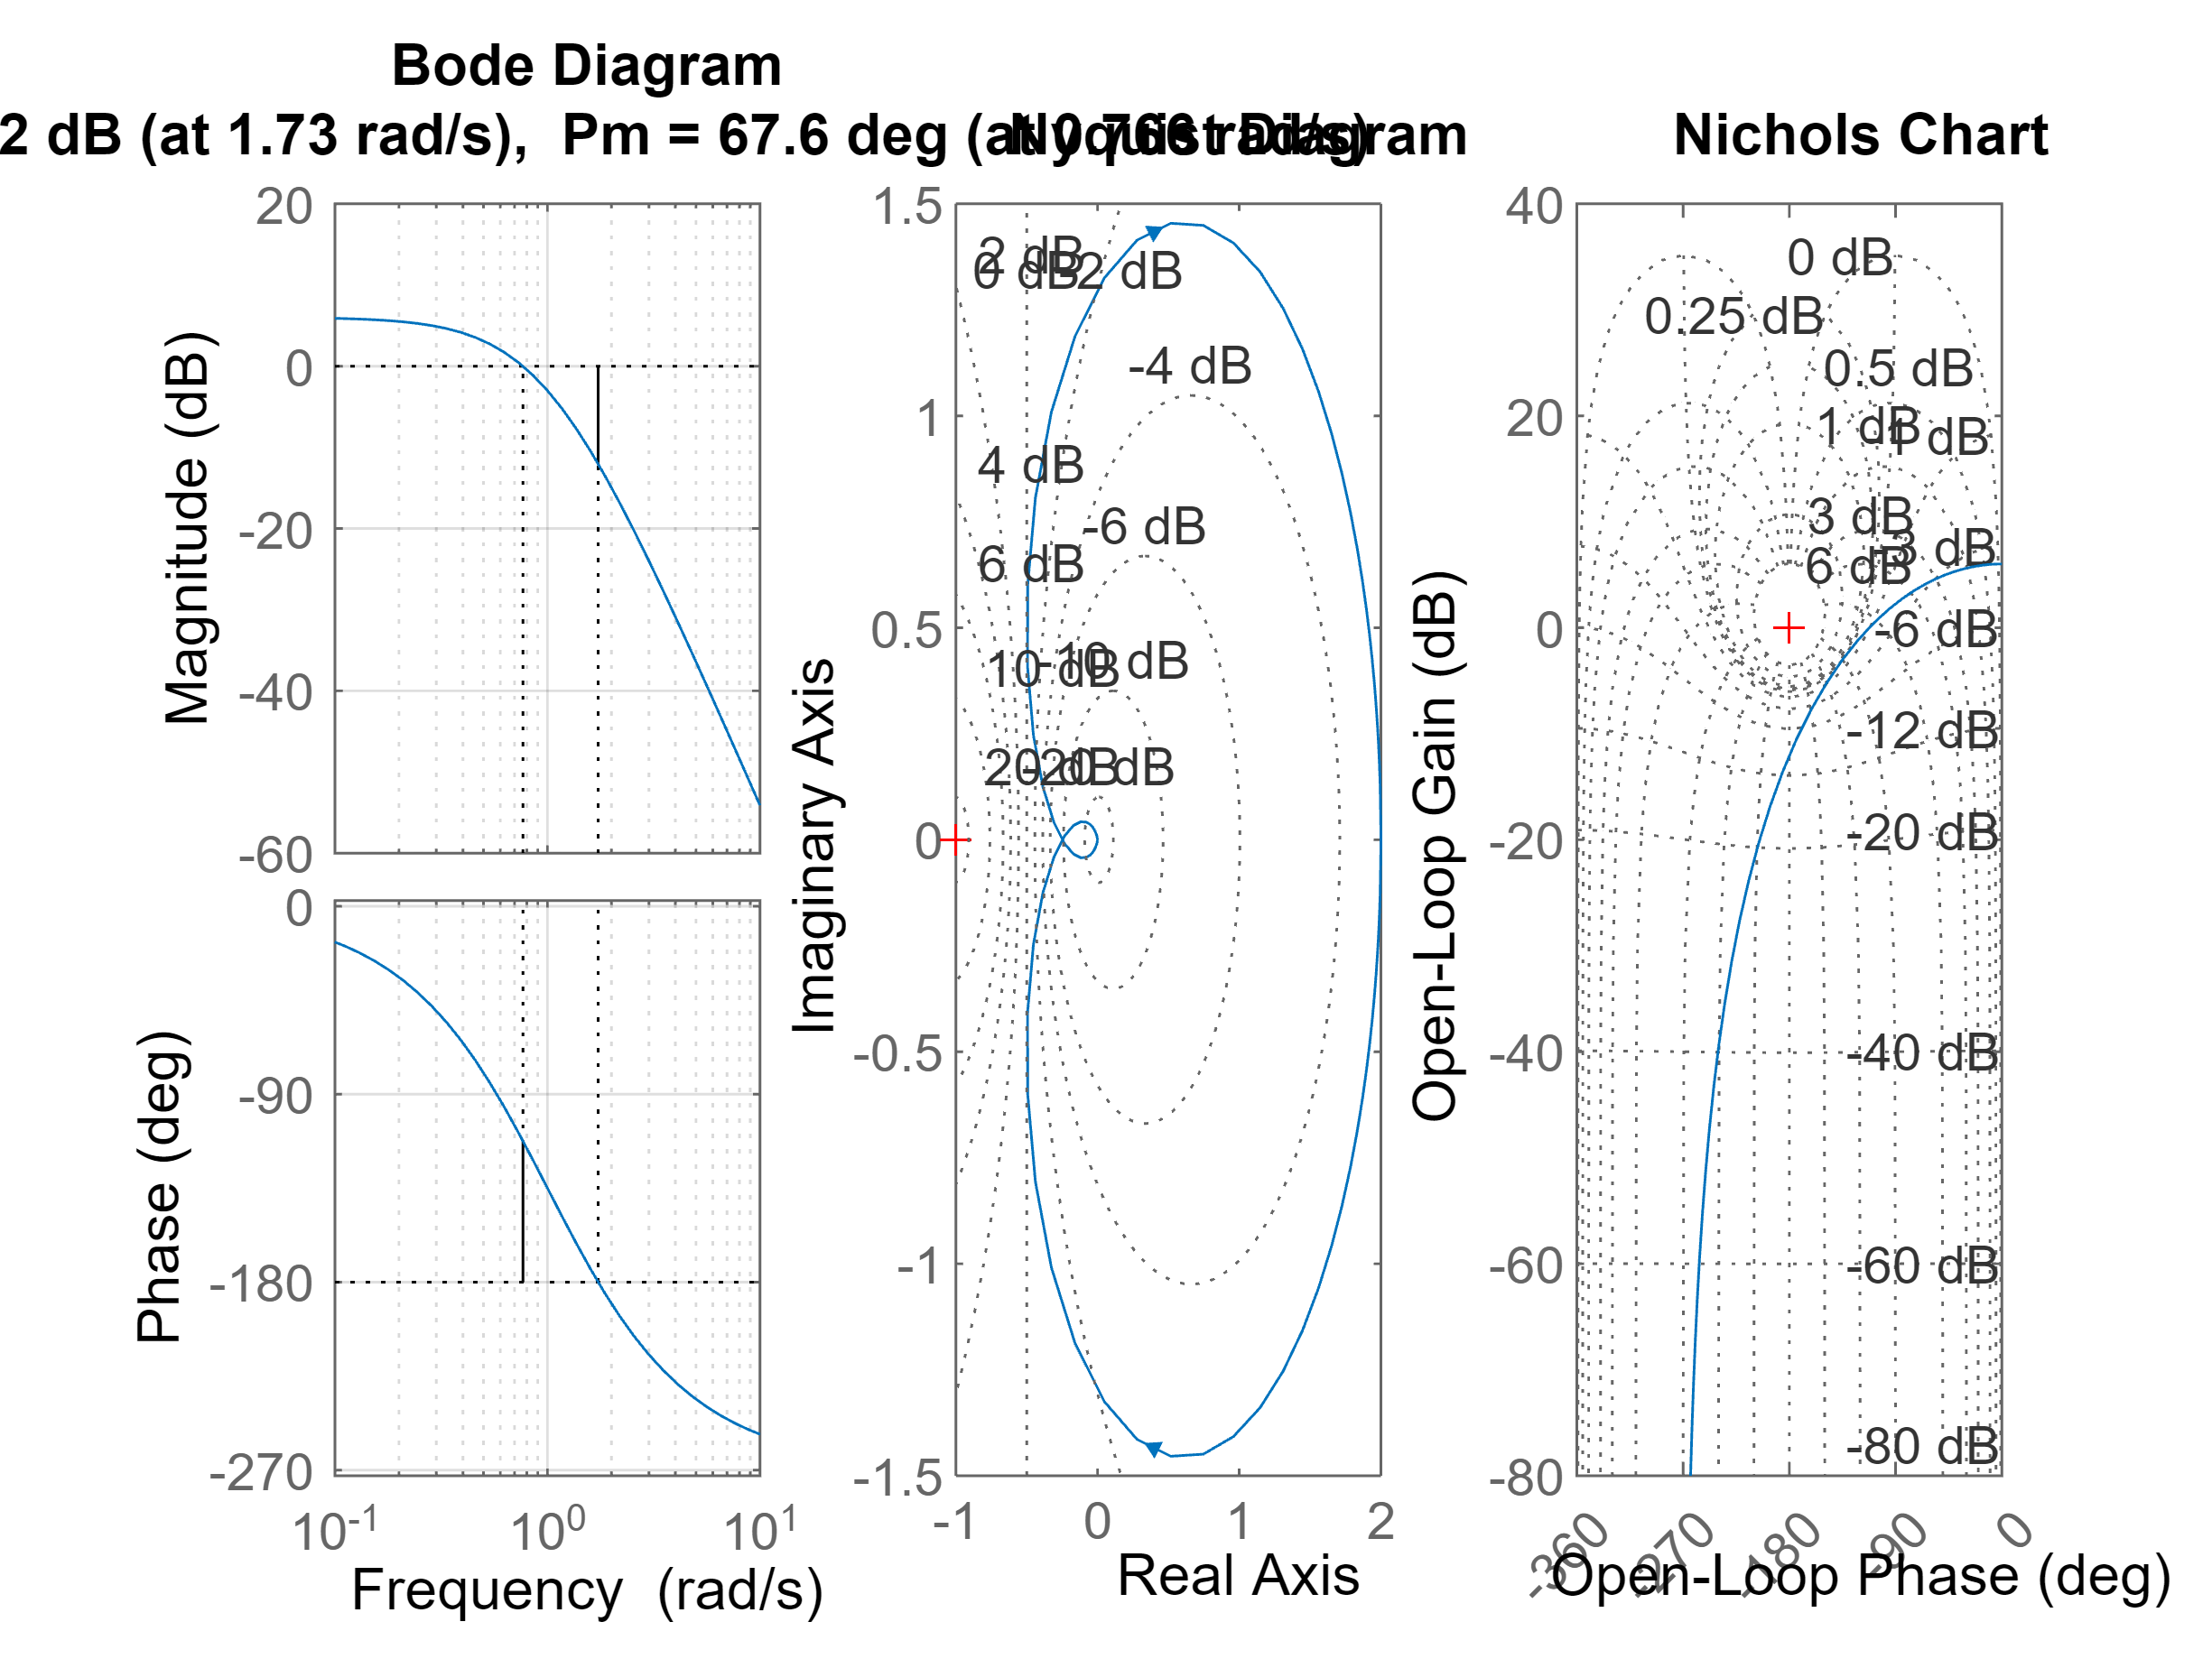

clear
close all
clc

s = tf('s');
G = 2/(s+1)^3; % k = 2

figure
subplot(131)
margin(G)
grid on

subplot(132)
nyquist(G)
grid on

subplot(133)
nichols(G)
grid on

Consider the system


$$L(s)=\frac{1+0.1s}{s^2+1}$$


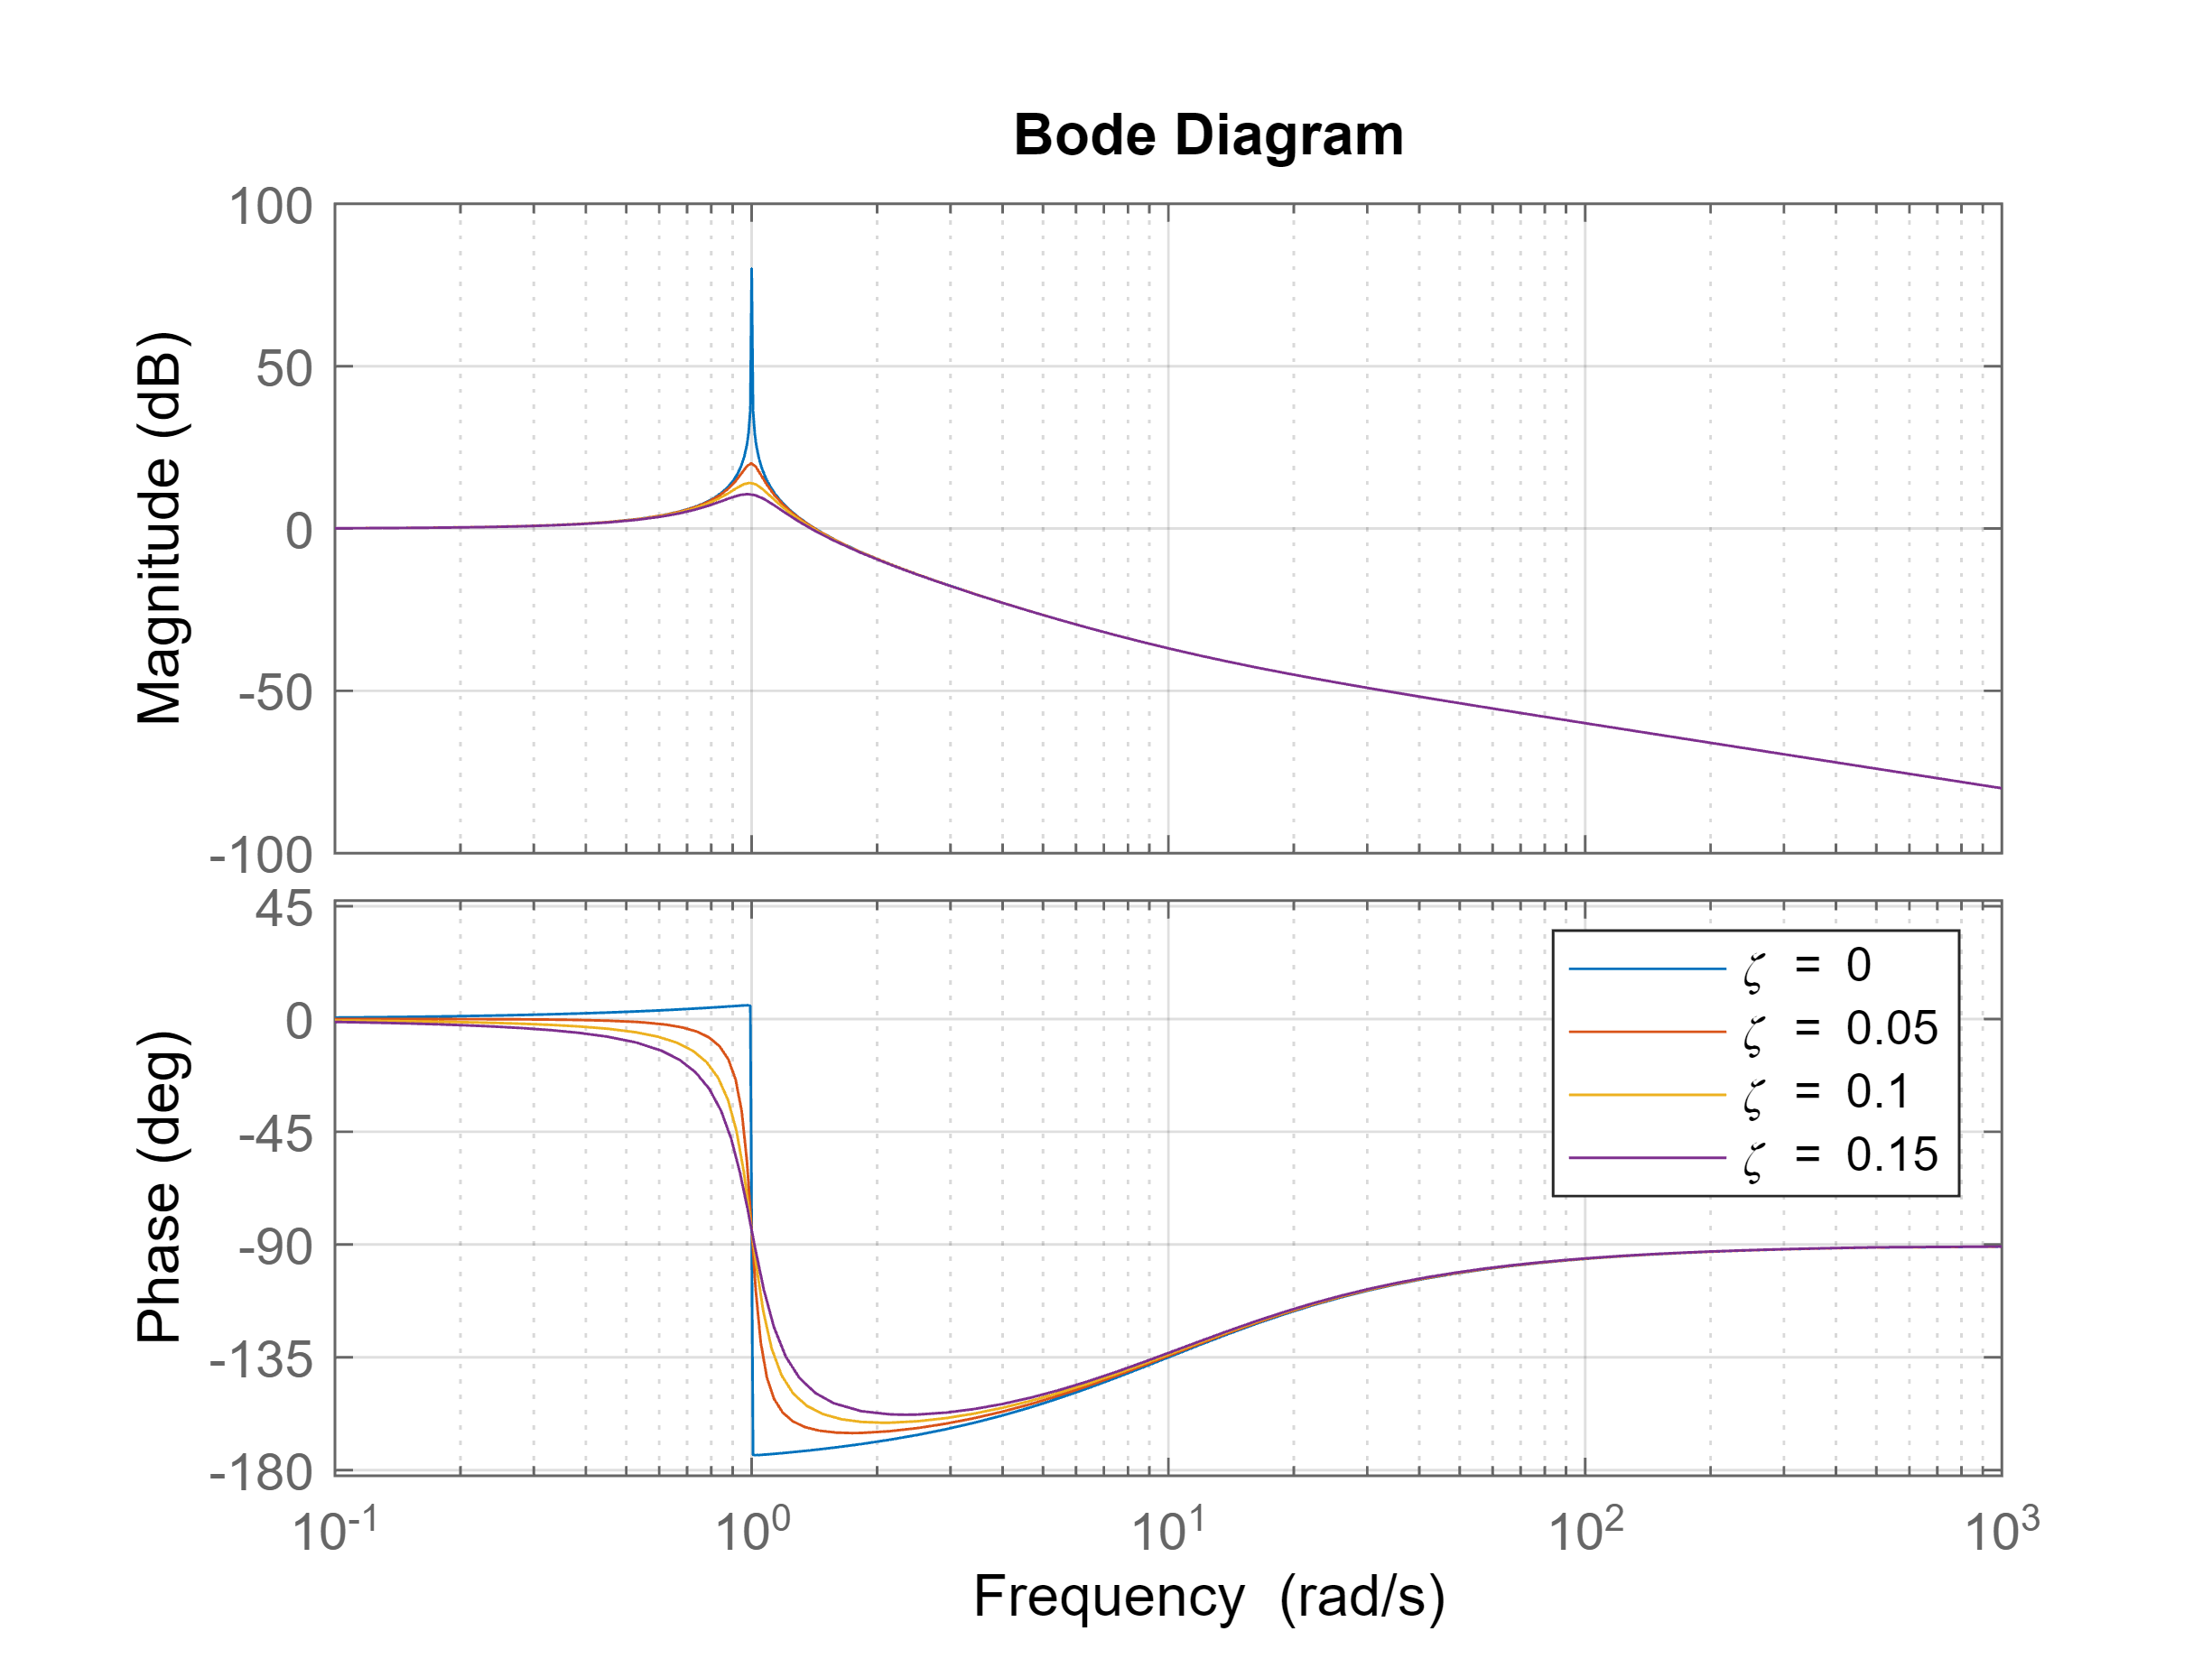

L = (1+0.1*s)/(1+s^2+0*s);

L1 = (1+0.1*s)/(1+s^2+0.1*s);
L2 = (1+0.1*s)/(1+s^2+0.2*s);
L3 = (1+0.1*s)/(1+s^2+0.3*s);



figure
bode(L,L1,L2,L3)
grid on
legend({'\zeta = 0','\zeta = 0.05','\zeta = 0.1','\zeta = 0.15'})

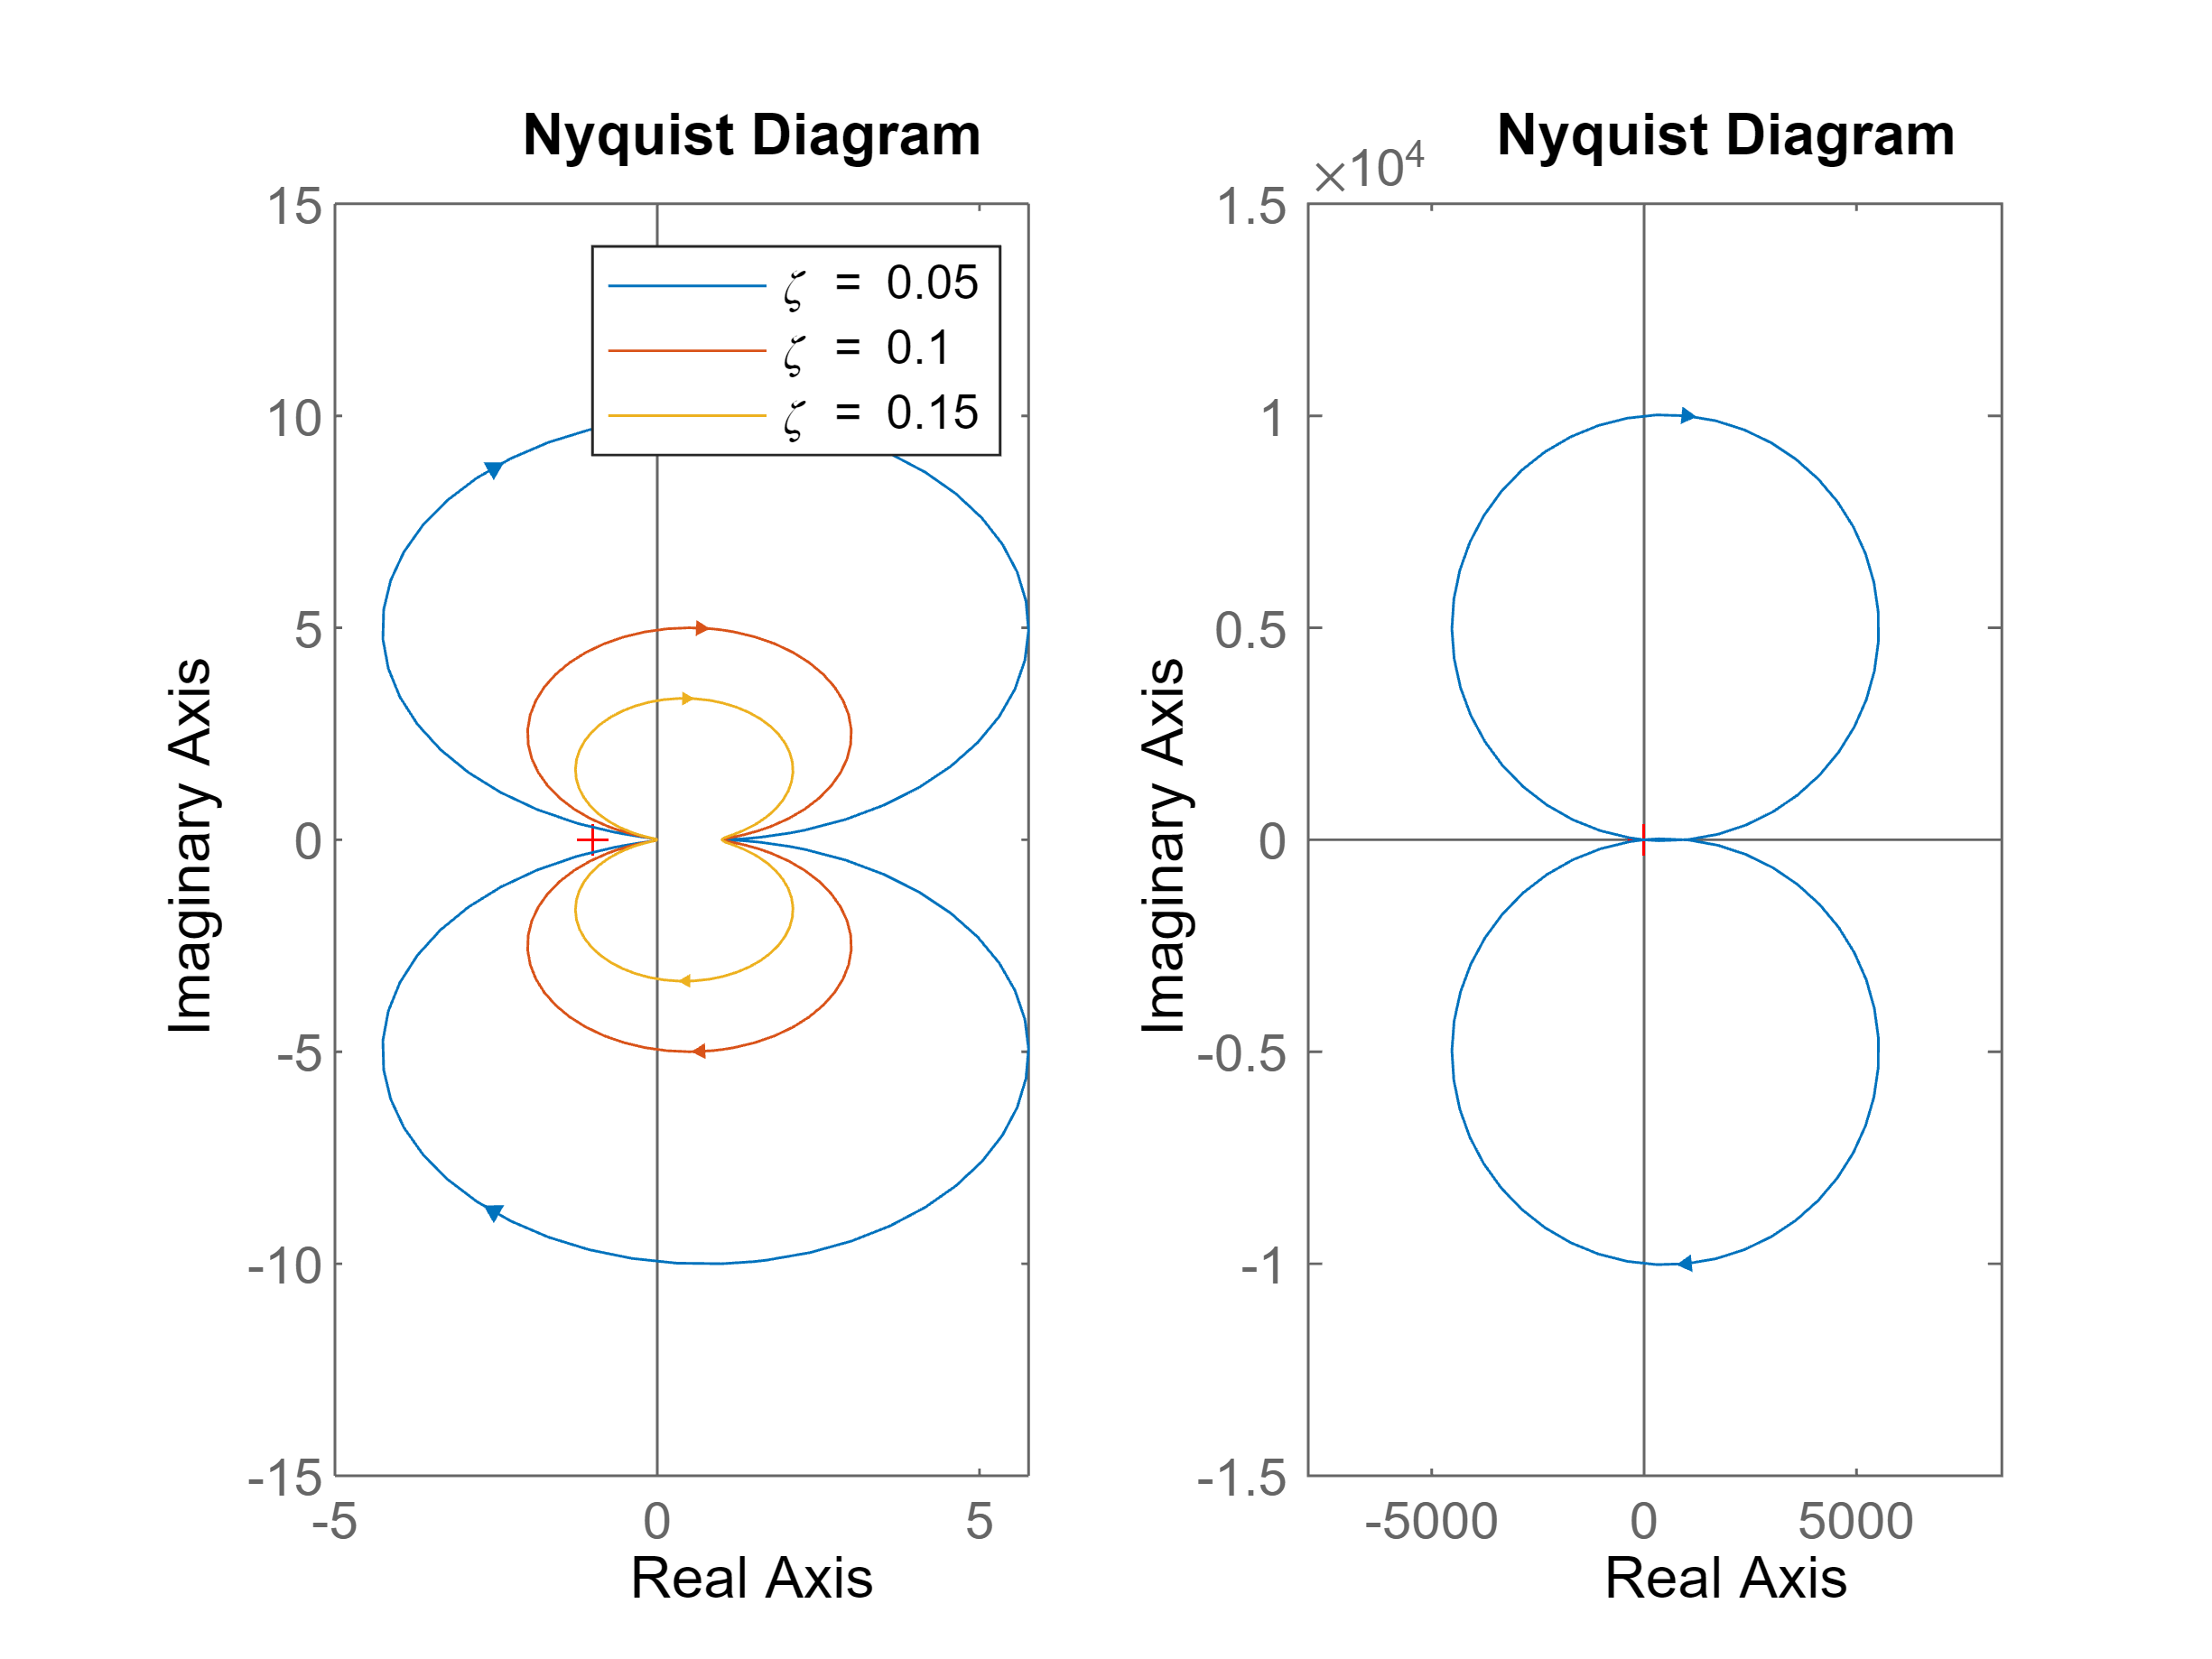



figure
subplot(121)
nyquist(L1,L2,L3)
legend({'\zeta = 0.05','\zeta = 0.1','\zeta = 0.15'})

subplot(122)
nyquist(L)
axis equal

Consider the system


$$L(s)=\frac{5}{s^2+s}$$


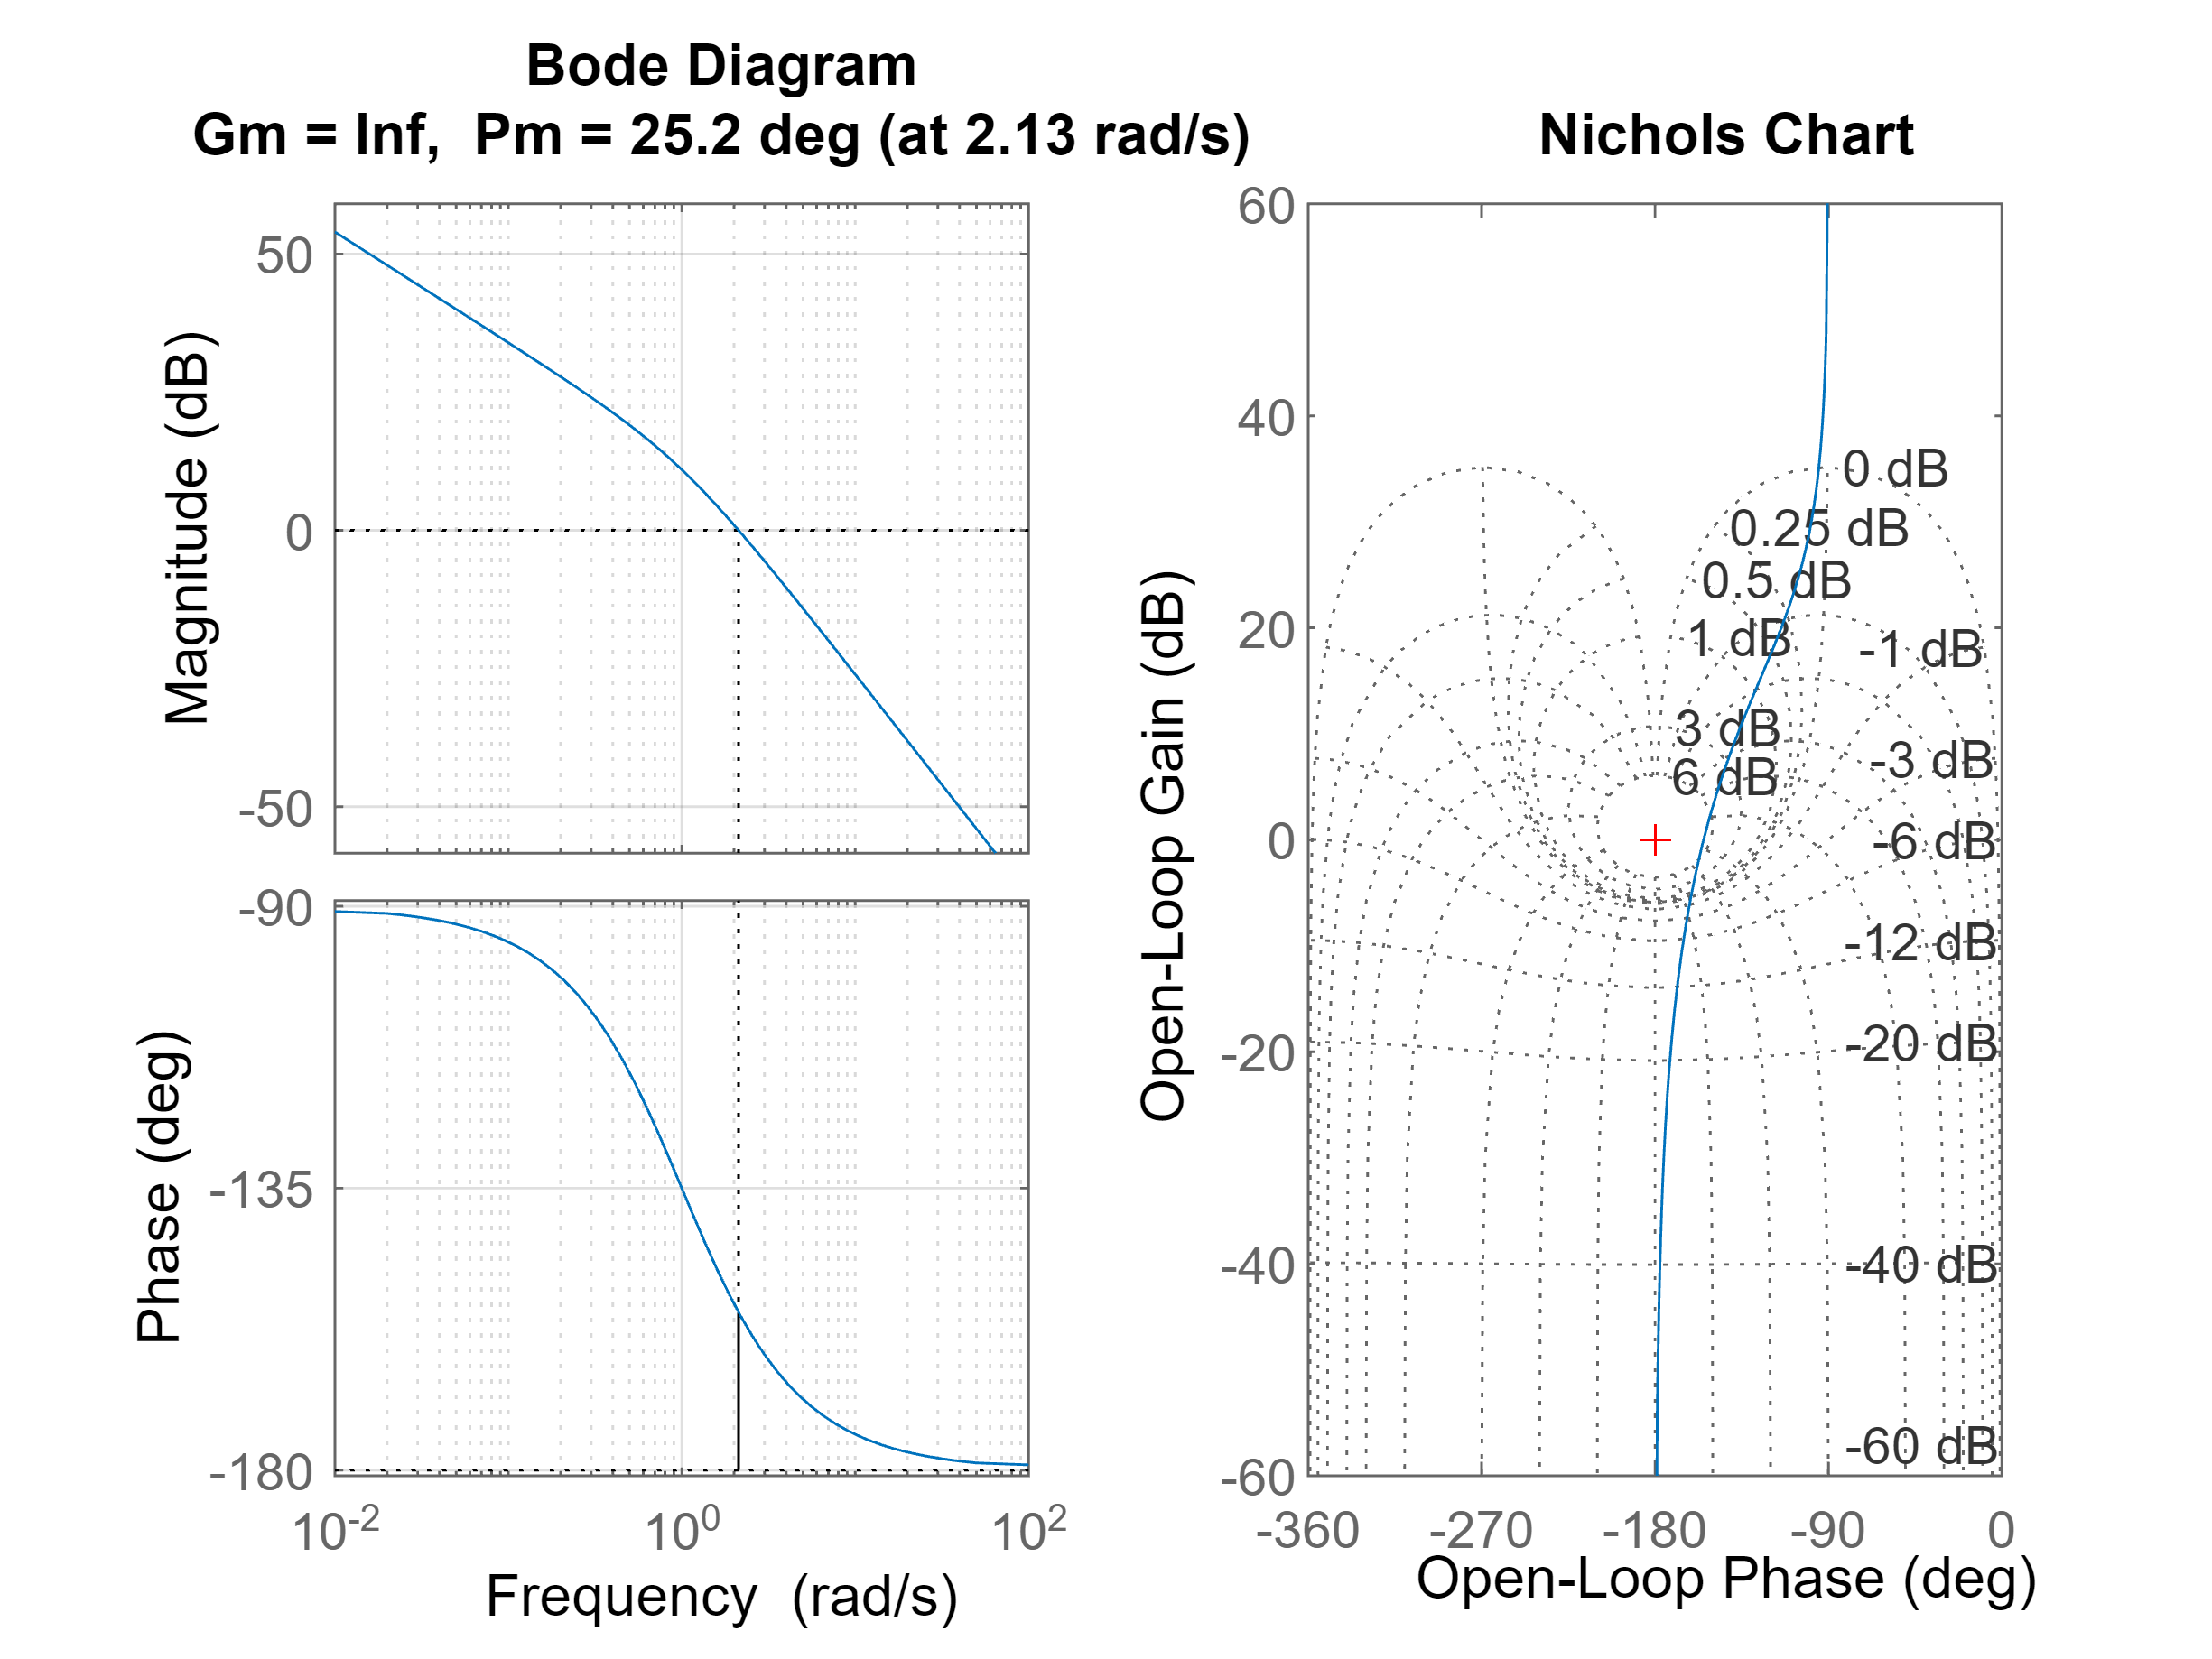

L = 5/(s^2+s);

figure
subplot(121)
margin(L)
grid on

subplot(122)
nichols(L)
grid on

Verify 3dB bandwidth and resonance peak on the closed loop tf

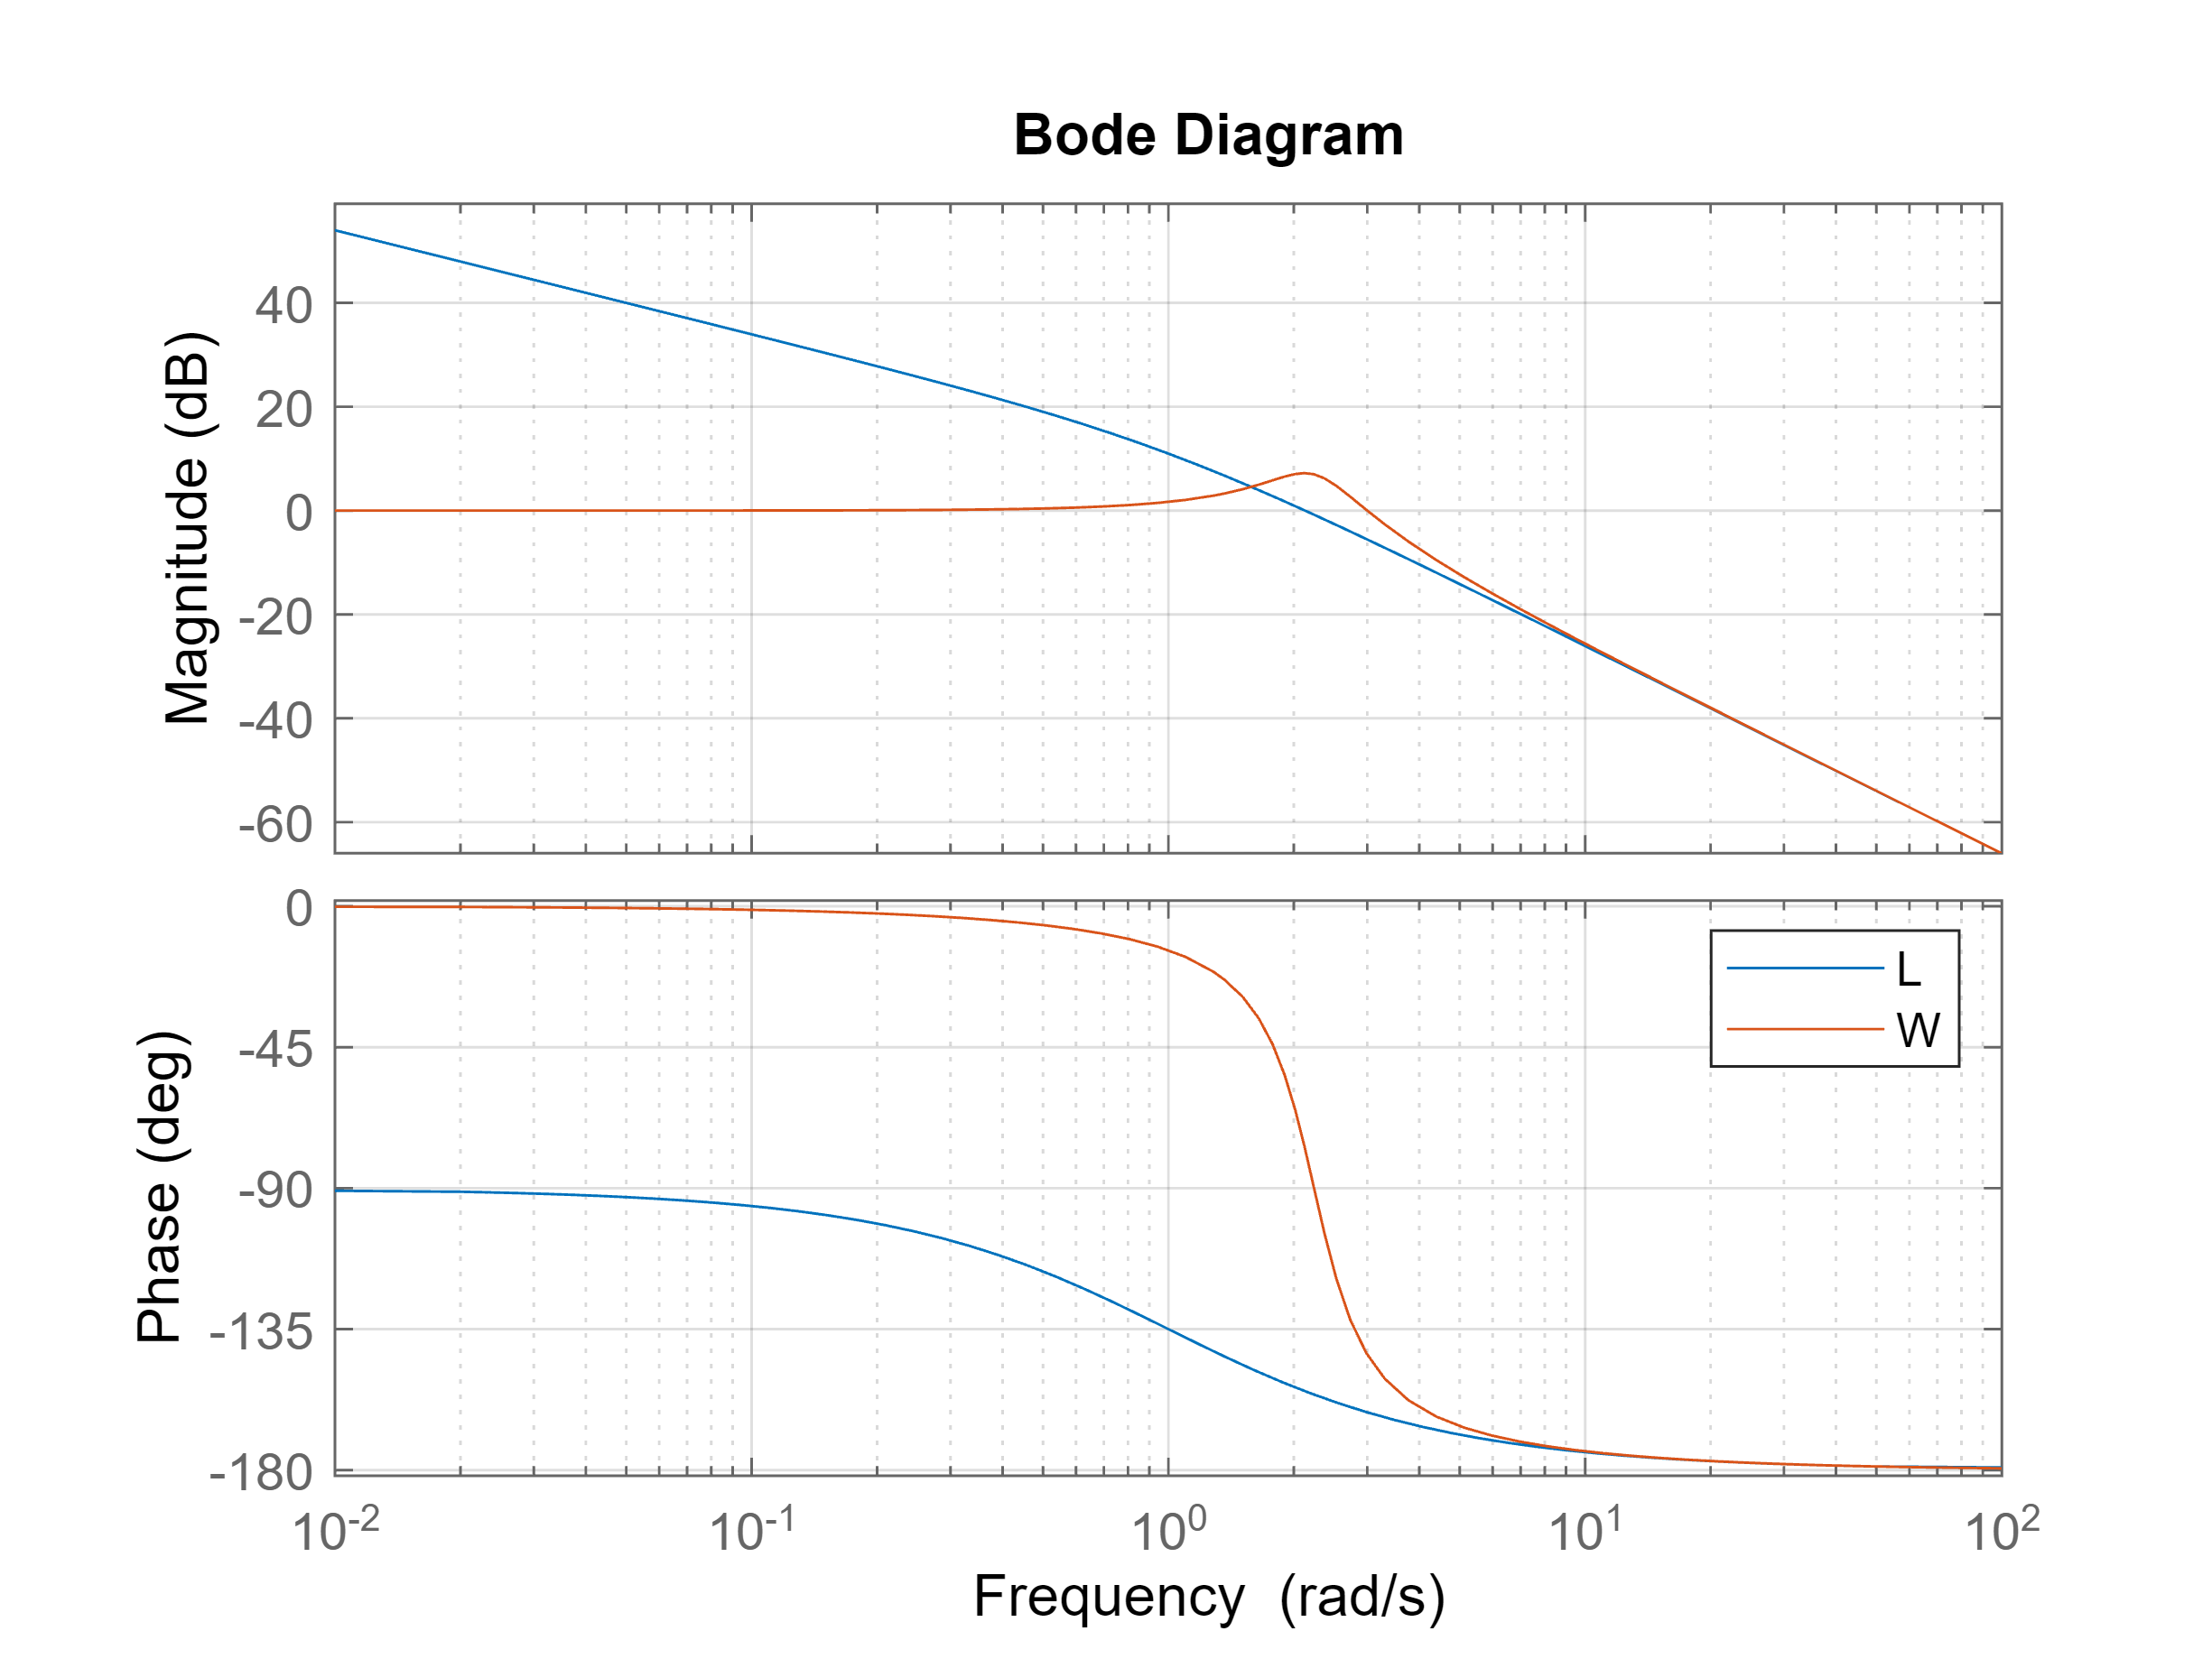

F = L/(1+L);
figure
bode(L)
grid on, hold on
bode(F)
legend('L','W')

Verify 2nd order approximation

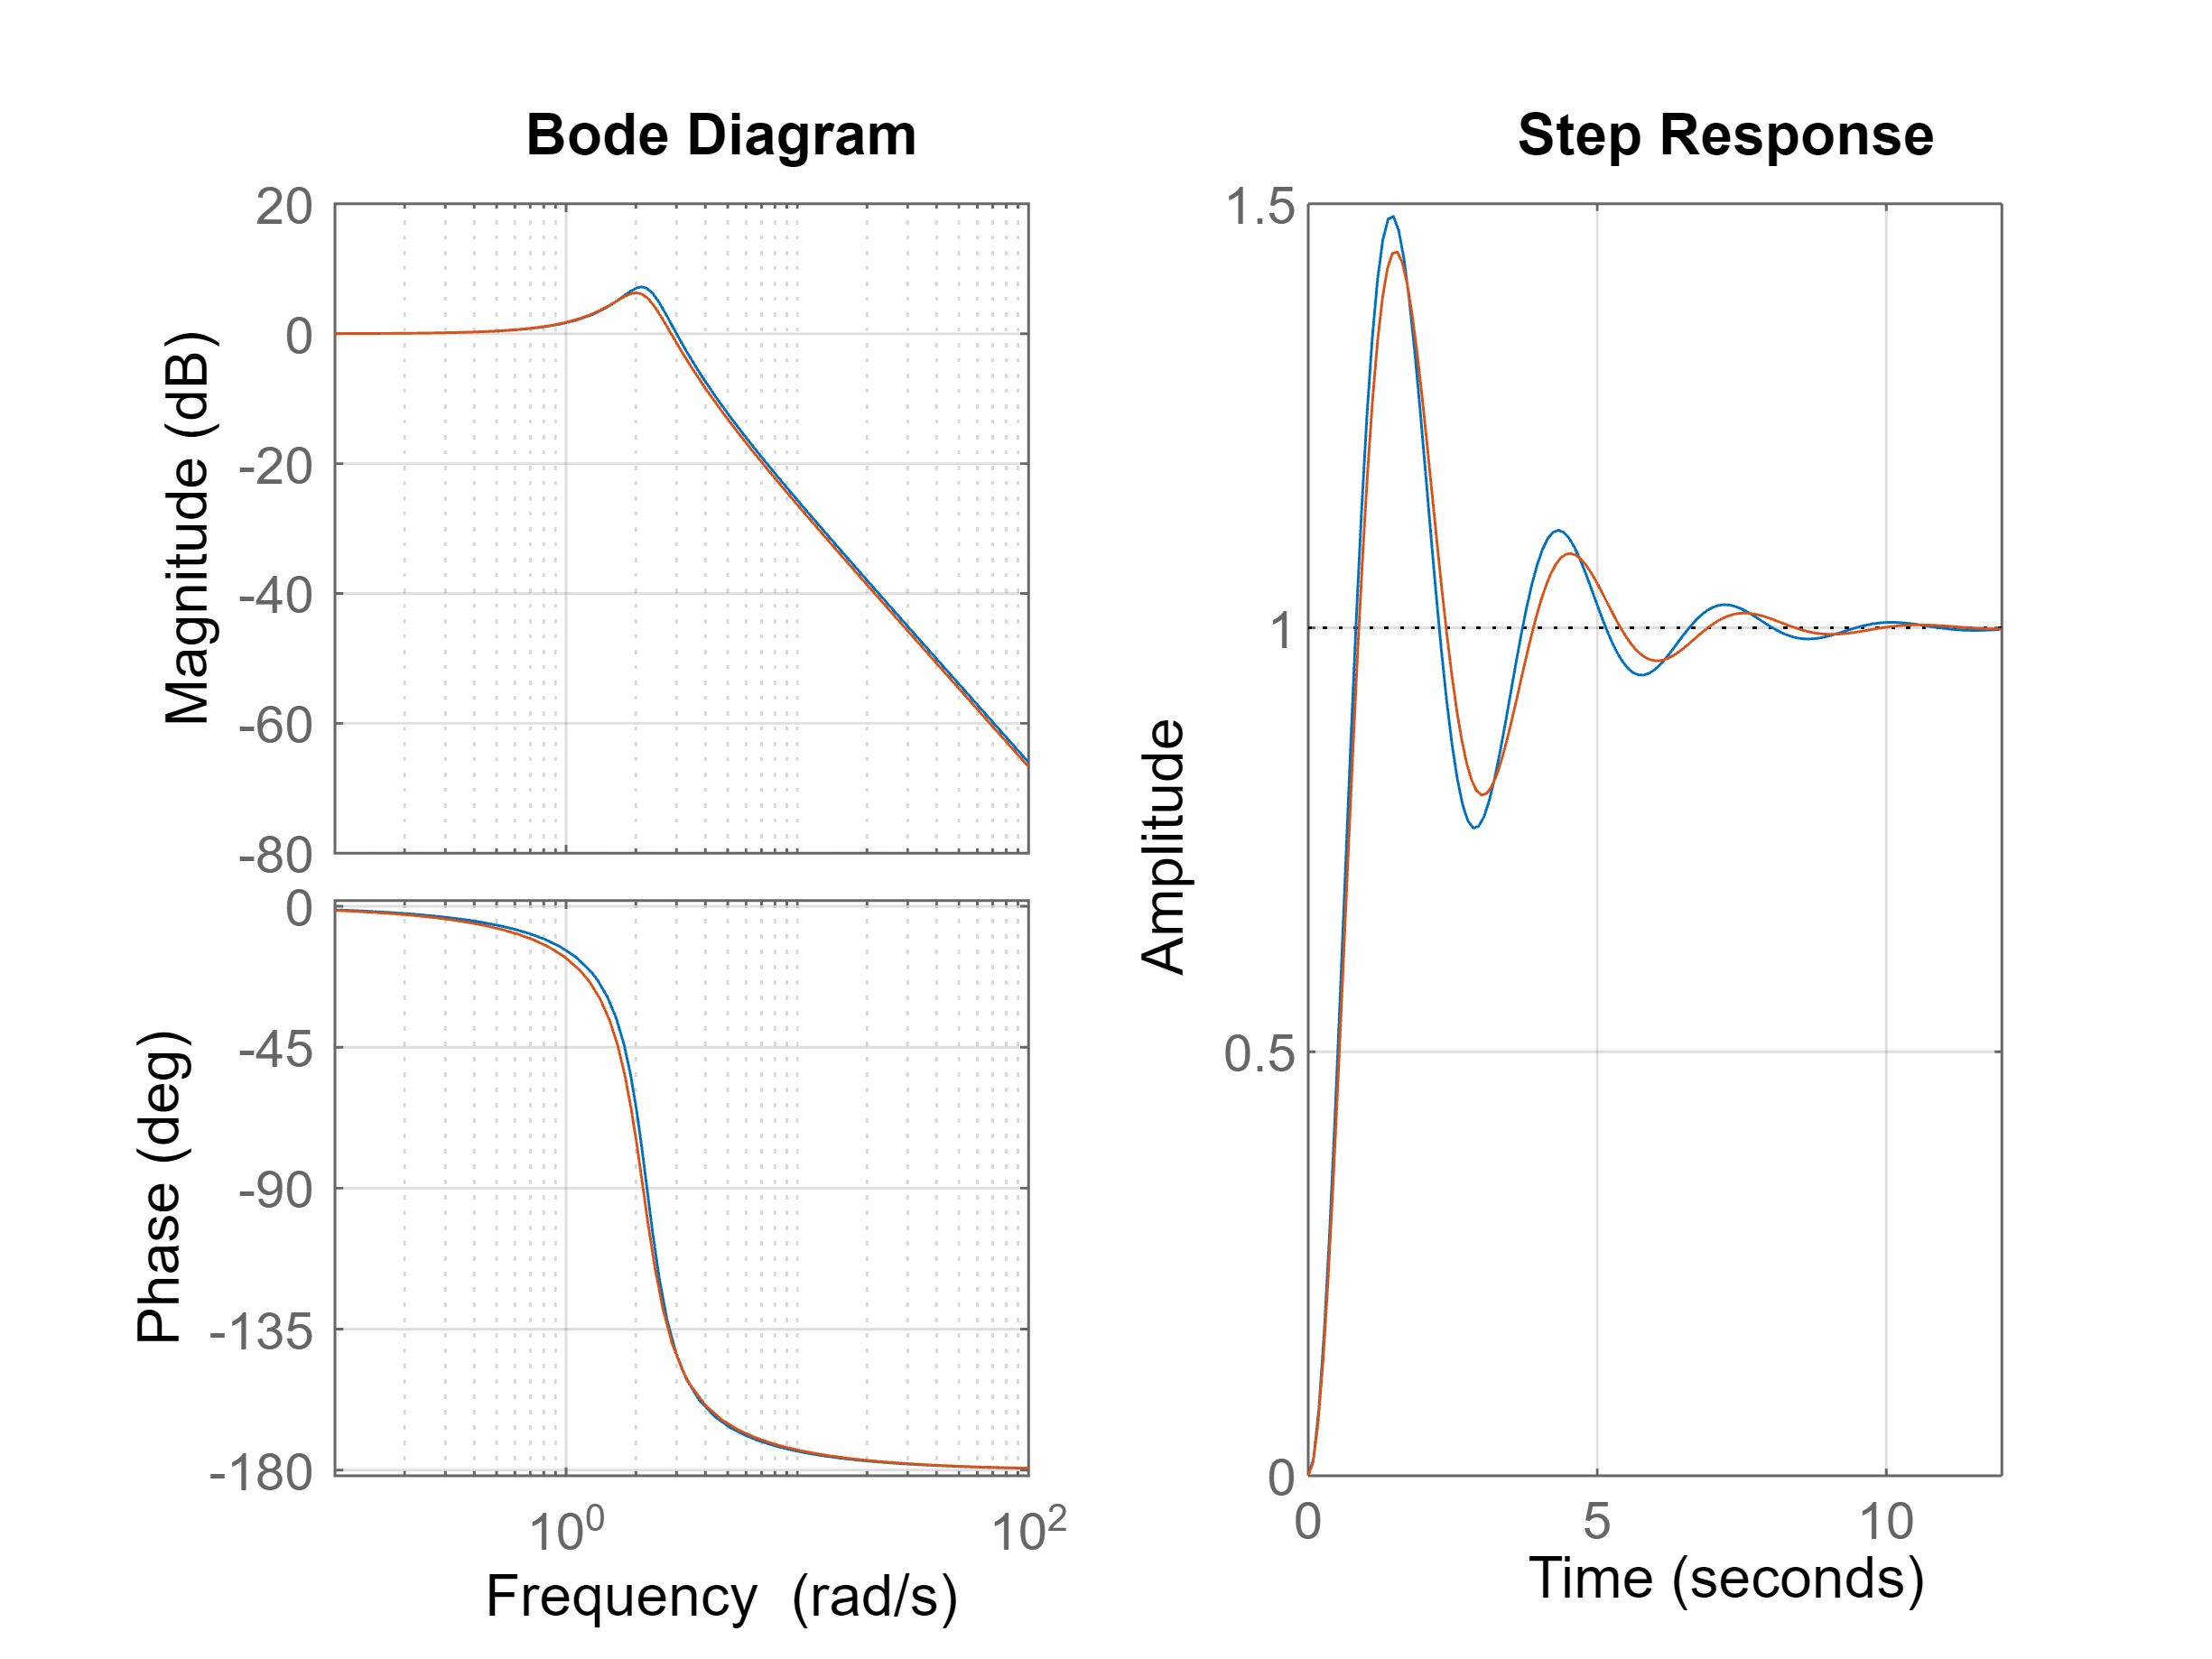

zeta = 0.25;
wn = 2.15;

F_approx = 1/(1+2*zeta*s/wn+s^2/wn^2);

figure
subplot(121)
bode(F,F_approx), grid on
subplot(122)
step(F);
hold on
step(F_approx);
grid on